# Microarray Data Analysis

In this homework, you are going to analyze microarray data from the following study: [http://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE7307.](http://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE7307.) The study contains gene expression profiles of 677 samples from 125 distinct tissue types with 12 different disease states (including normal state).

The main task is to segregate the gene expression profiles based on distinct tissue types and disease states.

Perform the analysis tasks described below and submit this mlx file (and any other auxilliary files you write for this assignment), the pdf version of this file, and the following files: *diseasegene.txt*, and *commongenes.txt*

## Objectives

- Understand the gene expression using microarray 

- Differential gene expression

- Familiar with the GEO repository hosted at NCBI [http://www.ncbi.nlm.nih.gov/geo/](http://www.ncbi.nlm.nih.gov/geo/)

- Understand the GEO structure,  GSE and GPL

- Download GEO data

- Understand the new  data type (DataMatrix), which is designed specifically for gene expression

- Map container function: containers.Map()

- Logical indexing

- Clustering and PCA analysis

- Volcano plot 

# Download & Parse Data

% Download and parse data
gse = loadGEO('GSE7307');

Loading cached data...
Done!


% Filter out genes with small profile variance
I = genevarfilter(gse.Data, 'Percentile', 99);
gse.Data = gse.Data(I, :); % Retain only genes with higher variation

fprintf('We will be analyzing a subset of the original dataset containing %d probes.', size(gse.Data, 1))

We will be analyzing a subset of the original dataset containing 547 probes.

% Get Platform ID from gse series
fprintf('Platform ID: %s', gse.Header.Series.platform_id);

Platform ID: GPL570

% Retrieve GPL data
gpl = loadGEO('GPL570');

Loading cached data...
Done!


% Remove unnecessary text from gse.Header.characteristics_ch1
gse.Header.Samples.characteristics_ch1(1,:) = cellfun(@(x) regexp(x, '(?<=Tissue\/Cell\ Line\ \[C\]: ).*', 'match'),...
	                                                    gse.Header.Samples.characteristics_ch1(1,:)); % Tissue types
gse.Header.Samples.characteristics_ch1(4,:) = cellfun(@(x) regexp(x, '(?<=Disease\ type: ).*', 'match'),...
	                                                    gse.Header.Samples.characteristics_ch1(4,:)); % Disease types

# Translate Probesets to Gene Symbols

% Get annoatation for GSE probes from GPL
map =  annotateProbes(gse, gpl, 'Gene Symbol');
% Replace any empty gene symbols with 'empty'
I = cellfun(@isempty, map.("Gene Symbol"));
map.("Gene Symbol")(I) = {'empty'};
%map.("Gene Symbol")(I) = map.ID(I); % appropriate probe ID
% Rename rows in data
gse.Data = gse.Data.rownames(':', map.("Gene Symbol"));

# Clustering Samples (Tissue Type and Disease State)

#### Use k-means clustering method to group all gene expression values into 4 clusters (independent from tissue type and disease state).

% Get the tissue and disease types that we are analyzing
tissue = gse.Header.Samples.characteristics_ch1(1, :); % 125 tissue types
diseaseType = unique(gse.Header.Samples.characteristics_ch1(4, :)); % 12 disease states (7 = Normal)
% Define boolean vector for selecting Normal patients
mask.Normal = strcmp(gse.Header.Samples.characteristics_ch1(4, :), 'Normal');

% Use kmeans to cluster the genes using the correlation method for
% computing distances
[clust,C] = kmeans(gse.Data, 4, 'dist', 'corr');

#### Investigate for each cluster, *do the samples from normal and disease state patients have overall similar expressionn profiles* (for all 12 diesease states)?

In this case, we are not segregating the tissue types.

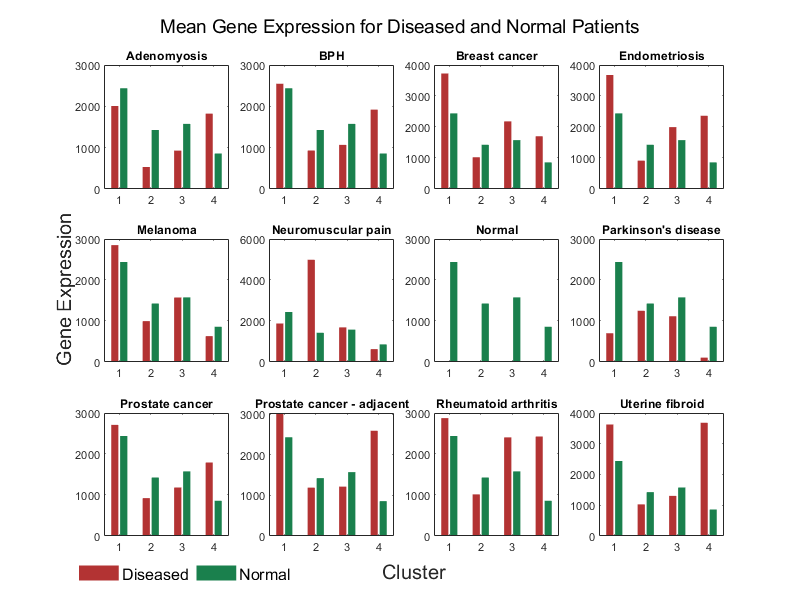

% Compare gene expression for diseased vs normal

fig = figure('Position', [0 0 800 600]); % Initialize figure

% For each disease type, compare the gene expression in diseased patients
% and normal patients
% In this analysis, Group 1 will always refer to Diseased patients, and Group
% 2 will always refer to normal patients.
for k = 1:numel(diseaseType)
	% Define boolean vector for selecting patients with current disease
	mask.Diseased = strcmp(gse.Header.Samples.characteristics_ch1(4, :), diseaseType{k});
	
	% Create a grouping vector
	G = zeros(size(gse.Header.Samples.characteristics_ch1(4,:)));
	G(mask.Diseased) = 1;
	G(mask.Normal) = 2;
	
	% Compute averages for each disease
	davg = zeros(4,2); % Col 1 - Grp 1, Col 2 - Grp 2
	for i = 1:4 % loop through clusters
		for j = 1:2 % loop through groups
			davg(i,j) = mean(gse.Data.double(clust == i, G == j), 'all');
		end
	end
	
	% Plot Results
	subplot(3,4,k);
	b = bar(davg, 'EdgeAlpha', 0); title(diseaseType{k});
	b(1).FaceColor = [.7 .2 .2]; b(2).FaceColor = [.1 .5 .3]; % Set bar colors
end

% Add title, labels, and legend to subplot grid
sgtitle('Mean Gene Expression for Diseased and Normal Patients');
lgd = legend({'Diseased', 'Normal'}, 'Orientation', 'horizontal', 'FontSize', 12, 'box', 'off');
lgd.Position = [0.12 0.03 0.2225 0.030];
h = axes(fig, 'visible', 'off'); h.XLabel.Visible = 'on'; h.YLabel.Visible = 'on';
xlabel(h, 'Cluster', 'FontSize', 15); ylabel(h, 'Gene Expression', 'FontSize', 15);

**Figure Caption: **This figure is a 4x3 grid of bar graphs showing the average gene expression of normal patients (green) and patients with a specific disease (red) for all 12 disease types in the dataset. The subplot titled 'Normal' only shows green bars since there was only one group in that iteration of the `for` loop.

**Figure Conculsion: **For most of the diseases in the figure, gene expression tends to follow a trend across the differnt clusters. Gene expression for both normal and diseased patients tends to be highest in Cluster 1, and decreases in clusters 2, 3 and 4 (the cluster numbers may change if the file is run again since `kmeans` generates clusters randomly). Overall, normal and diseased patients tend to have similar trends in their expression profiles, although they do vary in exact expression levels.

#### Investigate for tissue type 1 of each disease type. Within each cluster, do the sampels from normal disease and disease state have similar overall expression profiles (for all 12 disease states)?

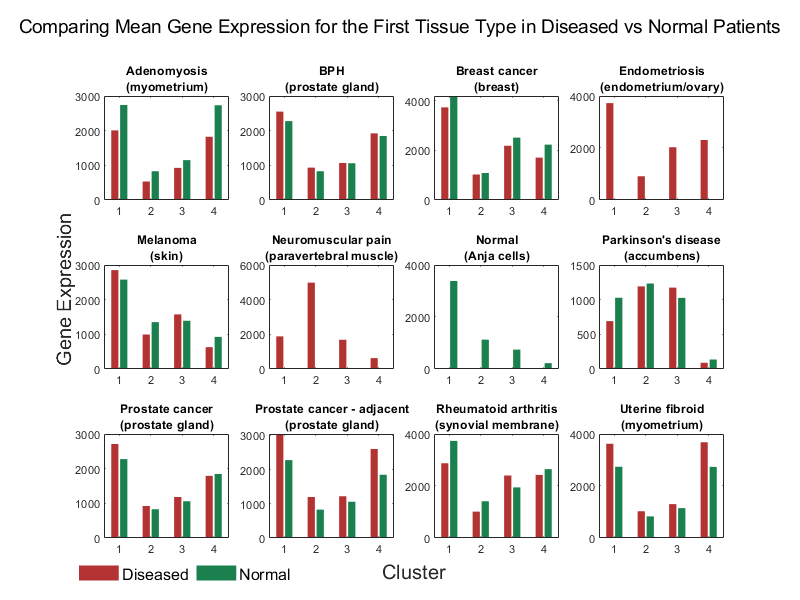

% Compare gene expression for tissue types for diseased vs normal (Only the
% first tissue type)

fig = figure('Position', [0 0 800 600]); % Initialize figure

% For each disease type, compare gene expression for the first tissue type
% in diseased and normal patients.
% In this analysis, Group 1 will always refer to Diseased patients, and Group
% 2 will always refer to normal patients.
for k = 1:numel(diseaseType)
	% Define boolean vector for selecting patients with current disease
	mask.Diseased = strcmp(gse.Header.Samples.characteristics_ch1(4, :), diseaseType{k});
	% Get the corresponding tissue types for this disease
	diseaseTissue = unique(tissue(mask.Diseased)); 
	% Define a boolean to select the first tissue type
	mask.tissue = strcmp(tissue, diseaseTissue{1});
	% Create a grouping vector
	G = zeros(size(gse.Header.Samples.characteristics_ch1(4,:)));
	G(mask.Diseased & mask.tissue) = 1;
	G(mask.Normal & mask.tissue) = 2;
	% Compute averages for each disease
	davg = zeros(4,2); % Col 1 - Grp 1, Col 2 - Grp 2
	for i = 1:4 % loop through clusters
		for j = 1:2 % loop through each group
			davg(i,j) = mean(gse.Data.double(clust == i, G == j), 'all');
		end
	end
	% Plot Results
	subplot(3,4,k);
	b = bar(davg, 'EdgeAlpha', 0); title({diseaseType{k}, ['(' diseaseTissue{1} ')']});
	b(1).FaceColor = [.7 .2 .2]; b(2).FaceColor = [.1 .5 .3];
end

% Add title, labels, and legend to subplot grid
sgtitle('Comparing Mean Gene Expression for the First Tissue Type in Diseased vs Normal Patients');
lgd = legend({'Diseased', 'Normal'}, 'Orientation', 'horizontal', 'FontSize', 12, 'box', 'off');
lgd.Position = [0.12 0.03 0.2225 0.030];
h = axes(fig, 'visible', 'off'); 
h.XLabel.Visible = 'on'; h.YLabel.Visible = 'on';
xlabel(h, 'Cluster', 'FontSize', 15); ylabel(h, 'Gene Expression', 'FontSize', 15);

**Figure Caption: **This figure is a 4x3 grid of bar graphs showing the average gene expression of normal patients (green) and patients with a specific disease (red) for the first tissue type of all 12 disease types in the dataset. The subplots titled 'Normal', 'Neuromuscular Pain', and 'Endometriosis' only show either green or red bars since there was only one group in that iteration of the `for` loop.

**Figure Conculsion: **The normal and disease state patients appear to exhibit different expression profiles. For some diseases, Adenomyosis for example, gene expression is higer in normal patients. While for others, Prostate cancer for example, gene expression is higher in diseased patients.

# Differential Gene Expression in Disease

What are the genes that are differentially expressed in each disease? For each disease, compare the disease samples with the normal samples of the same tissue. Save the results into an Excel worksheet named `diseasegene` , with the header row contianing `"disease"`, `"gene"`, `"pvalue"`, `"negfoldchange"`. Only show significant genes. Gety disease type.

***In this dataset, the gene expression number is not on a logarithmic scale.***

### Objectives:

- The main goal is to segregate the patients based on both diseasetype and tissuetype.

- 677 patients (columns) and each patient has a defined disease type and a tissue type. 

- `	disease type:`` gse.Header.Samples.characteristics_ch1(4, :)` 

- `	tissue type: ``gse.Header.Samples.characteristics_ch1(1, :)`

- Unique 12 disease types (1-12) and redefine 11 disease states 1-6 and 8-12 of the disease types plus 7 as the normal

- Unique 125 tissue types

- For each patient (677), who should have a disease state (total 12), associated tissue types (total 125)

- ***Go through each disease state and its associated unique tissue types to compare the gene expression of normal tissue and disease tissue.***

- For example, disease state 1 "adenomyosis" has only one unique tissue type, "myometrium". You will compare gene expression between normal myometrium and diseased myometrium. Disease state 2 may have several unique tissue types.

- Loop through disease states and unique tissue types associated witht the disease states to find the significant genes.

- Everything is based on a logical index (1x677)

- `mask.Normal` indicates patients are normal

- `mask.Diseased` patients have a certain disease

- `mask.Tissue` patient with a certain disease and a certain tissue type.

- write/record every significant gene in a text file.

% Exclude normal patients from disease type list
diseaseState = diseaseType(~strcmp(diseaseType, 'Normal'));
% Initialize results
DEG = table(); % Differentially Expressed Genes

% Loop through disease states
% In this analysis, Group 1 will always refer to Diseased patients, and Group
% 2 will always refer to normal patients.
for i = 1:numel(diseaseState)
	% Create a mask for patients with the current disease
	mask.Diseased = strcmp(gse.Header.Samples.characteristics_ch1(4, :), diseaseState{i});
	% Get corresponding tissue types for this disease
	diseaseTissue = unique(tissue(mask.Diseased));
	
	% Loop through tissue types
	for j = 1:numel(diseaseTissue)
		% Create boolean mask for current tissue
		mask.tissue = strcmp(tissue, diseaseTissue(j));
		
		% Create booleans to define groups fors comparison
		mask.G1 = mask.Diseased & mask.tissue; % Group 1 = Patients with this tissue type and disease
		mask.G2 = mask.Normal & mask.tissue; % Group 2 = Normal patients with this tissue type
		
		% Do not compute comparisons if either group is empty
		if ~any(mask.G1) || ~any(mask.G2)
			fprintf('For %s there is only one dataset, so there is no significance.\n', diseaseState{i})
		else
			% Compute pvalues comparing normal and diseased patients with this
			% tissue type
			dpvals = mattest(gse.Data(:, mask.G1), gse.Data(:, mask.G2), 'permute', 1000);
			% Find the mean intensity (gene expression) for each group
			avg.G1 = mean(gse.Data(:, mask.G1), 2);
			avg.G2 = mean(gse.Data(:, mask.G2), 2);
			% Compute the fold change
			fc = avg.G1 ./ avg.G2;
			% Select only significantly differentially expressed genes from dpvals,
			% fc and from the map table
			I = (dpvals(:,1) < 0.01);
			dpvals = dpvals(I, :); fc = fc(I, :);
			geneList = gse.Data.RowNames(I);
			% Create cell array with the current disease
			disease = repmat(diseaseState(i), size(dpvals(:, 1)));
			% Append data
			DEG = [DEG; table(disease, geneList, dpvals.double, fc)];
		end
	end
end

For Endometriosis there is only one dataset, so there is no significance.
For Neuromuscular pain there is only one dataset, so there is no significance.


% Set Variable names in output
DEG.Properties.VariableNames = {'Disease', 'Gene Symbol', 'p-Value', 'Fold Change'};
% Write data to diseasegene.txt
writetable(DEG, 'diseasegene.txt');

# Commonly Altered Genes in Diseases

Now, based on the above results, we will try to answer the question: *Are there any genes commonly differentially expressed for different diseases?* For each of the differentially expressed genes you found, report the number of genes they are involved in. Save the results to a text file named `commongenes,` with the header row containing 'gene', 'numdiseases', 'diseaselist' (CSV for diseases that the gene is found in).

% Find all unique significantly expressed genes
sigGenes = unique(DEG.("Gene Symbol"));
% Preallocate table columns
numdiseases = zeros(size(sigGenes));
diseaselist = cell(size(sigGenes));

% Loop through the significant genes and grab he number of diseases they
% were involved in by indexing for the gene and summing the logical array.
% Then get the list of genes by combining the disease names into one cell.
for i = 1:numel(sigGenes)
	mask.genes = strcmp(DEG.("Gene Symbol"), sigGenes{i}); % Boolean for selecting the current gene
	numdiseases(i) = sum(mask.genes); % Get the number of diseases
	diseaselist{i} = strjoin(unique(DEG{mask.genes, "Disease"}), ', '); % Create the disease list
end

% Create & Write Output Table
geneCount = table(sigGenes, numdiseases, diseaselist,...
	                'VariableNames', {'DEGenes', 'NumDiseases', 'DiseaseList'});
writetable(geneCount, 'commongenes.txt', 'Delimiter', '\t');

# Bonus: Housekeeping Genes

Housekeeping genes are those that are required for the maintenance of basic cellular function and are typically constitutively expressed. Using only the normal tissue samples, can you find the house keeping genes? You need to make your own assumptions and analysis. Explain how you decide to define annd find the housekeeping genes. Save your results to a text file named "housekeeping". In addition to the gene names, report "housekeepingness" of these genes, accoridng to the criteria you came up with.

## Housekeeping Genes

Housekeeping genes are necessary for maintianing basic cellular function. Thus, they are expressed in virtually all cell types under normal physiological conditions. 

To identify housekeeping genes in this dataset, first, I will identify differentially expressed genes between Normal patients and diseased patients. Next, I will determine how many tissue types each gene is significantly differentially expressed in. The genes that are significant for the largest number of cell types are housekeeping genes. The *housekeepingness* of each gene will be the number of cells that a particular gene is significant for.

% Initialize output table
tissueExpr = table(); % Tissue expression
% Get all tissue types
normalTissue = unique(tissue(mask.Normal));

% Loop through tissue types
for i = 1:numel(normalTissue)
	% Create mask for this tissue
	mask.tissue = strcmp(tissue, normalTissue{i});
	% Define groups for comparison
	mask.G1 = mask.Normal & mask.tissue; % Normal patients with this tissue type
	mask.G2 = ~mask.Normal & mask.tissue; % Diseased patients with this tissue type
	% Only compare if both groups are not empty
	if any(mask.G1) && any(mask.G2)
		% Compute pvalues
		dpvals = mattest(gse.Data(:, mask.G1), gse.Data(:, mask.G2));
		% Select only significantly differentially expressed genes
		I = (dpvals(:, 1) < 0.01);
		dpvals = dpvals(I, :);
		geneList = gse.Data.RowNames(I);
		% Create a cell array with the current tissue type
		thisTissue = repmat(normalTissue(i), size(geneList));
		% Append data
		tissueExpr = [tissueExpr; table(thisTissue, geneList, dpvals.double)];
	end
end

% Find all unique significantly expressed genes
sigGenes = unique(tissueExpr.geneList);
% Preallocate table columns
numcells = zeros(size(sigGenes));
cells = cell(size(sigGenes));

% Loop through the significant genes and grab the number of tissues they
% were involved in by indexing for the gene and summing the logical array.
% Then get the list of genes by combining the tissue names into one cell.
for i = 1:numel(sigGenes)
	mask.genes = strcmp(tissueExpr.geneList, sigGenes{i}); % Boolean for selecting the current gene
	numcells(i) = numel(unique(tissueExpr.thisTissue(mask.genes)));
	cells{i} = strjoin(unique(tissueExpr{mask.genes, "thisTissue"}), ', ');
end

% Create & Write Output Table
houseGenes = table(sigGenes, numcells, cells,...
	                'VariableNames', {'DEGenes', 'Housekeepingness', 'CellList'});
writetable(houseGenes, 'housekeeping.txt', 'Delimiter', '\t');